# Cleaning Workspace

clear;
close all;
clc;

# Initialization Parameters

## Massive MIMO Parameters

Parameters of a Massive MIMO systems with $$M$$-antennas base station, $K$ single-antenna user terminals, and $N$multipaths.

M = 500;                                                             % Number of Antennas
K = 2;                                                               % Number of Users
N = 50;                                                              % Number of Multipaths

m = (0:M-1).';

## Cell Parameters

Parameters of an hexagonal cell with interfering objects

R = 500;                                                             % Cell's raidus (circumradius) in meters
r = sqrt(3)/2*R;                                                     % Cell's inradius in meters

x_cell = [R R/2 -R/2 -R -R/2 R/2 R]';                                % Cell's x-coordinates
y_cell = [0 r    r    0 -r  -r   0]';                                % Cell's y-coordinates

city = 'LARGE';

H_bs = 30;                                                           % Height of base station in meters

H_user_min = 1.50;                                                   % Minimum height of user terminals in meters
H_user_max = 2.20;                                                   % Maximum height of user terminals in meters

H_user = H_user_min + (H_user_max - H_user_min)*rand(K,1);           % Height of user terminals in meters

H_object_min = H_user_max;                                           % Minimum height of interfering objects in meters
H_object_max = H_bs;                                                 % Maximum height of interfering objects in meters

H_object = H_object_min + (H_object_max - H_object_min)*rand(N,1);   % Height of interfering objects in meters

## Propagation Parameters

Parameters regarding the signal propagation

c      = 3e8;                                                        % Light speed
f_c    = 1.6e9;                                                      % Carrier frequency in Hz
lambda = c/f_c;                                                      % Wavelength of transmitted signal
d = lambda/2;                                                        % Antenna spacing of transmitt array

mean_shadow_fad_dB = 0;                                              % Shadow fading mean in dB
mean_shadow_fad    = 10^(mean_shadow_fad_dB/20);                     % Shadow fading mean      

std_dev_shadow_fad_dB = 8;                                           % Shadow fading standard deviation in dB
std_dev_shadow_fad    = 10^(std_dev_shadow_fad_dB/20);               % Shadow fading standard deviation

mu_shadow_fad = log(mean_shadow_fad^2/sqrt(std_dev_shadow_fad^2 + mean_shadow_fad^2));
                
sigma_shadow_fad = sqrt(log((std_dev_shadow_fad/mean_shadow_fad)^2 + 1));

## Coordinates Initialization

x_object = zeros(K,N);
y_object = zeros(K,N);

# Sorting User Positions and Calculating the Line of Sight (LoS) and non LoS Departure Angles

## Genarating User Terminals Position

Choosing user terminal coordinates inside the hexagonal cell.

aux_cord = rand(K,1);

K_1 = sum(aux_cord < 1/3);
K_2 = sum(aux_cord < 2/3 & aux_cord > 1/3);

u = rand(K,1);
v = rand(K,1);

u_1 = u(1:K_1,1);
v_1 = v(1:K_1,1);

u_2 = u(K_1+1:K_1+K_2,1);
v_2 = v(K_1+1:K_1+K_2,1);

u_3 = u(K_1+K_2+1:K,1);
v_3 = v(K_1+K_2+1:K,1);

x_1 = -R/2*u_1 + R*v_1;
y_1 = r*u_1;

x_2 = -R/2*u_2 - R/2*v_2;
y_2 = -r*u_2 + r*v_2;

x_3 = R*u_3 - R/2*v_3;
y_3 = -r*v_3;

x_user = [x_1' x_2' x_3']';
y_user = [y_1' y_2' y_3']';

d_bs_user = sqrt(x_user.^2 + y_user.^2);                                % Distance between base station and users in meters
r_bs_user = sqrt(d_bs_user.^2 + (H_bs - H_user).^2);                    % Length of the path traveled by the signal in meters

theta_user = atan2(y_user,x_user);                                      % Departure angle in rad
theta_user_degree = theta_user*180/pi                                   % Departure angle in degree

theta_user_degree =   146.8863
  -63.4990


## Generating Interfering Objects Positions

for k = 1:K
    for n = 1:N
        if(x_user(k) >= 0)
            x_object(k,n) = x_user(k)*rand(1);
            y_object(k,n) = -r + 2*r*rand(1);
            
            if(x_user(k) > R/2)
                while(y_object(k,n) + 2*r/R*x_object(k,n) - 2*r > 0 || ...
                      y_object(k,n) - 2*r/R*x_object(k,n) + 2*r < 0)
                    x_object(k,n) = x_user(k)*rand(1);
                    y_object(k,n) = -r + 2*r*rand(1);
                end
            end
        else
            x_object(k,n) = x_user(k) - x_user(k)*rand(1);
            y_object(k,n) = -r + 2*r*rand(1);
            
            if(x_user(k) < -R/2)
                while(y_object(k,n) - 2*r/R*x_object(k,n) - 2*r > 0 || ...
                      y_object(k,n) + 2*r/R*x_object(k,n) + 2*r < 0)
                    x_object(k,n) = x_user(k) - x_user(k)*rand(1);
                    y_object(k,n) = -r + 2*r*rand(1);
                end
            end
        end
    end
end

theta_object = atan2(y_object,x_object);                                % Departure angle in rad
theta_object_degree = theta_object*180/pi                               % Departure angle in degree

theta_object_degree =   163.0549 -119.8925  -90.8048  112.6616  169.7594 -125.5511  100.0054  116.9380 -105.3754 -132.3121 -169.6397  106.7315  136.1740  124.4918 -103.4683  111.6124   99.3515  131.8449  132.8333  100.2083 -155.3971 -167.0597 -117.8217 -103.6594  114.2760  122.5490  -98.5088 -101.1565  122.8940   93.3418  -93.9290  124.0945  112.4130  110.2094   95.1374 -104.9062  129.5113  110.0192  114.8766  154.2252  115.9497  115.8998 -137.1676  113.0853 -113.5916  -97.3290  123.8207   97.5657   98.0040 -144.1723
  -21.1886   69.6542  -69.5717  -70.6170  -58.3768  -87.6555   28.1229   83.8202   79.1908  -53.3662   60.1262  -84.7076   82.9838   26.7662  -77.7272  -78.6205   80.9100  -77.6994   49.0248   65.7324  -83.8038  -63.1641  -89.2330  -73.6167  -74.1586  -80.6059   89.2519   30.5935   82.8293  -18.3163  -68.6587   74.7172   70.3917   77.9031  -89.1742   46.4929   59.4879   57.8483  -86.6075   89.5693   10.2609  -84.2750   73.7520   57.8573  -67.0199  -75.1964   60.9822  -88.1

# Ploting Cell and Users

## Ploting Parameters

linewidth = 2;
fontname = 'Times New Roman';
fontsize = 20;
markersize = 10;

## Uuniform LoS (U-LoS) Channel

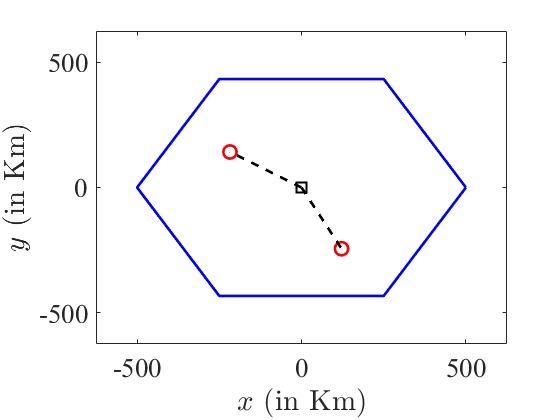

figure;

plot(x_cell,y_cell,'-b','linewidth',linewidth);
hold on;
plot(0,0,'sk','linewidth',linewidth,'markersize',markersize);
plot(x_user, y_user,'or','linewidth',linewidth,'markersize',markersize);
for k = 1:K
    plot([0 x_user(k)],[0 y_user(k)],'--k','linewidth',linewidth)
end
xlabel('$x$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$y$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

set(gca,'fontname',fontname,'fontsize',fontsize);
xlim([-1.25*R 1.25*R]);
ylim([-1.25*R 1.25*R]);

## Sparse Multipath Channel

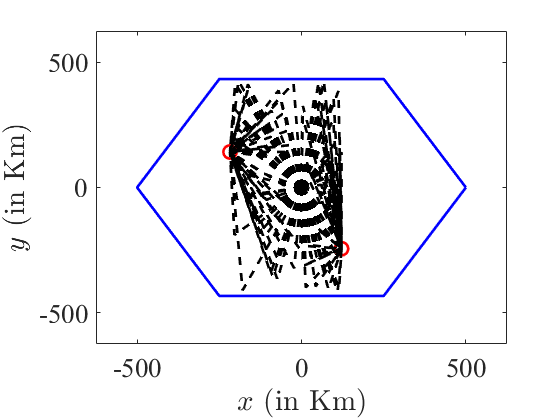

figure;

plot(x_cell,y_cell,'-b','linewidth',linewidth);
hold on;
plot(0,0,'sk','linewidth',linewidth,'markersize',markersize);
plot(x_user, y_user,'or','linewidth',linewidth,'markersize',markersize);
for k = 1:K
    for n = 1:N
        plot([0 x_object(k,n) x_user(k)],[0 y_object(k,n) y_user(k)],'--k','linewidth',linewidth)
    end
end
xlabel('$x$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$y$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

set(gca,'fontname',fontname,'fontsize',fontsize);
xlim([-1.25*R 1.25*R]);
ylim([-1.25*R 1.25*R]);

# Generating Channel Matrices

## Shadow Fading

Shadow fading is log-normally distributed

z = lognrnd(mu_shadow_fad,sigma_shadow_fad,K,1);                % Shadow fading

## Path Loss Calculation

Pass loss is computed using the COST-231 Hata model

switch city
   
    case 'LARGE'
        if((150 <= f_c/1e6) && (f_c/1e6 <= 200))
            C_h = 8.29*(log10(1.54*H_user)).^2 - 1.1;
        elseif((200 < f_c/1e6) && (f_c/1e6 <= 2000))
            C_h = 3.2*(log10(11.75*H_user)).^2 - 4.97;
        else
        end
        C = 3;
    case 'MEDIUM'        
        C_h = 0.8 + (1.1*log10(f_c/1e6) - 0.7)*H_user - 1.56*log10(f_c/1e6);
        C = 0;
    case 'SMALL'
        C_h = 0.8 + (1.1*log10(f_c/1e6) - 0.7)*H_user - 1.56*log10(f_c/1e6);
        C = 0;
    otherwise
        error('Invalid type of city');
end

path_loss_dB = -(46.30 + 33.90*log10(f_c/1e6) - 13.82*log10(H_bs) - C_h + (44.9 - 6.55*log10(H_bs))*log10(r_bs_user/1e3) + C) % Path loss in dB

path_loss_dB =  -116.2362
 -117.3116


path_loss    = 10.^(path_loss_dB/10);                                                                                         % Path loss

## Large-scale Fading Coefficient

The large-scale coefficient is independent of the small-scale effects and depend only the path loss and the shadow fading

beta    = z.*path_loss;                                           % Large-scale fading
beta_dB = 10.*log10(beta)                                         % Large-scale fading in dB

beta_dB =  -125.9181
 -132.2807


## Idependent Rayleigh Fading (Rich Scattering Fading)

G_rich = (randn(M,K) + 1i*randn(M,K))/sqrt(2);
H_rich = G_rich*sqrt(diag(beta));                                       % Uplink channel matrix

vecnorm(G_rich,2).^2

ans =   508.7004  473.0265


var(G_rich)

ans =     1.0189    0.9470


vecnorm(H_rich,2).^2

ans = 	1.0e+-9 *

    0.1302    0.0280


## Uniformly Random LoS Fading

steering_vector_ur_los = steeringVector(M,theta_user,d,lambda);

g_ur_los = (randn(1,K) + 1i*randn(1,K))/sqrt(2);
G_ur_los = repmat(sqrt(beta').*g_ur_los,M,1);

H_ur_los = G_ur_los.*steering_vector_ur_los;                             % Uplink channel matrix

## Sparse Multipath Fading

H_sm = zeros(M,K);

for k = 1:K
    steering_vector_sm = steeringVector(M,theta_object(k,:)',d,lambda);
    
    g = (randn(N,1) + 1i*randn(N,1))/sqrt(2);
    
    H_sm(:,k) = sqrt(beta(k))*steering_vector_sm*g;
end

## Orthogonality Deficiency

od_rich   = orthogonalityDeficiency(H_rich);                            % Orthogonality deficiency calculation
od_ur_los = orthogonalityDeficiency(H_ur_los);                          % Orthogonality deficiency calculation
od_sm     = orthogonalityDeficiency(H_sm);                              % Orthogonality deficiency calculation

disp(['Orthogonality Deficiency for Rich Sacattering Fading: ' num2str(od_rich)   newline ...
      'Orthogonality Deficiency for UR-LoS Fading:           ' num2str(od_ur_los) newline ...
      'Orthogonality Deficiency for Sparse Multipath:        ' num2str(od_sm)]);

Orthogonality Deficiency for Rich Sacattering Fading: 0.00092523
Orthogonality Deficiency for UR-LoS Fading:           4.5709e-06
Orthogonality Deficiency for Sparse Multipath:        0.0022347


# Functions

## Steering Vector

function steering_vector = steeringVector(M,theta,d,lambda)

m   = (0:M-1)';
tau = d*sin(theta)/lambda;
Tau = repmat(tau',M,1);

steering_vector = exp(-2*pi*1i*Tau.*repmat(m,1,size(theta,1)));

end

## Orthogonality Deficiency

function [od] = orthogonalityDeficiency(channel_matrix)

od = real(1 - det(channel_matrix'*channel_matrix)/prod(vecnorm(channel_matrix).^2));

end